**PositionControlDCServo2022.mlx contains and support the RoboClawServoArduino functions**

Place a brief description of what your code does here

Define the inputs the system takes in here as well as any outputs generated

Jack Levitsky and Ben Morris, 03,03,2022, Revision #A

clc             %clear command window
clear           %clear MATLAB workspace

**Set up robot control system **(code that runs once)

%Create arduino and arduino position servo
[robotArduino, positionServo, blinkLED]=SETUPARDUINO('COM7');   % COM7 for Jack AND Ben (wooooo!!!)

Warning! Robotic Claw should be off right now!
Power up the Claw Now


%Turn on board LED on and off signal to show we have started
Blink(robotArduino,blinkLED,3);
disp('Warning! Position Servo Active!');

Warning! Position Servo Active!


%Configure test loop to collect n data points
nTests=input(['Enter number of servo test positions, ' 'followed by enter:']);

%create a variable to hold experimental position data
positionData= zeros(nTests,2);
r=rateControl(.25);  %1hz loop rate control object created
 reset(r);          %reset loop time to 0

**Run robot control loop **(code that runs over and over)

 controlFlag = 1;           %create a loop control
 while (controlFlag <= nTests)
    commandAngle = SENSE();    %Get data from robot sensors
    THINK();    %Compute what robot should do next
    ACTRoboClawServoArduino(positionServo, commandAngle);      %Command robot actuators\

    % Store actual vs target angles
    positionData(controlFlag, 1) = input('Enter actual fish position in degrees:  ');
    positionData(controlFlag, 2) = commandAngle;

    % Blink LED
    Blink(robotArduino, blinkLED, 1)

    waitfor(r)          %wait for loop to complete
    controlFlag = controlFlag + 1;
 end

ans = 3

ans = 6

ans = 3

ans = 4

**Displaying Data**

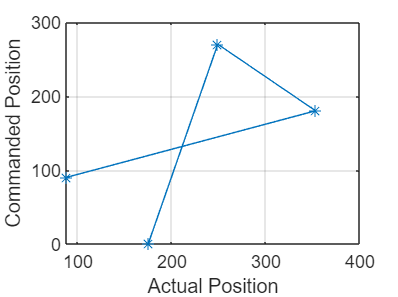

 %Plot commanded position vs actual position
 plot(positionData(:,1), positionData(:,2), '-*')
 xlabel('Actual Position')
 ylabel('Commanded Position')
 grid

**Clean Shutdown**

 writePosition(positionServo, 0.5);
 clc;
 disp('Arduino program has ended');

Arduino program has ended


 clear robotArduino
 beep   % Play system sound to let user know program has ended
 beep   % Play again for good measure.

**Robot Functions** (store the code's local functions here)

To make things readable, modular, and reusable, your main robot code is as brief as possible while the majority of work is completed by functions

 function [robotArduino, positionServo, blinkLED]=SETUPARDUINO(COMPORT)
q=input(['Ensure RoboClaw is off, then hit enter']);

 robotArduino=arduino(COMPORT, 'Uno', 'Libraries', 'Servo');
 disp('Warning! Robotic Claw should be off right now!');

 blinkLED = 'D13';
 configurePin(robotArduino,blinkLED, 'DigitalOutput');

 positionServo=servo(robotArduino,'D9','MinPulseDuration',10*10^-6, 'MaxPulseDuration', 1925*10^-6);

 writePosition(positionServo,.5);
w=input(['Power up RoboClaw, then hit enter']);

disp("Power up the Claw Now");
 end

 function Blink(a, LED, n)
    % Blink toggles Arduino a's LED on and off to indicate program running
    % Input n is number of blinks
    % No output

    for bIndex = 1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2);
        writeDigitalPin(a, LED, 1);
        pause(0.2);
    end
 end

**Sense Functions **(store all sense related functions here)

 function commandAngle = SENSE()
    % Prompt user for fish angle
    commandAngle = input('Enter desired servo angle in degrees:  ');
end

**Think Functions **(store all think related functions here)

function THINK()
% no thoughts, head empty
end

**Act Functions **(store all act related functions here)

function ACTRoboClawServoArduino(positionServo, commandAngle)

scaleComAngle=commandAngle/360;
writePosition(positionServo,scaleComAngle);
end